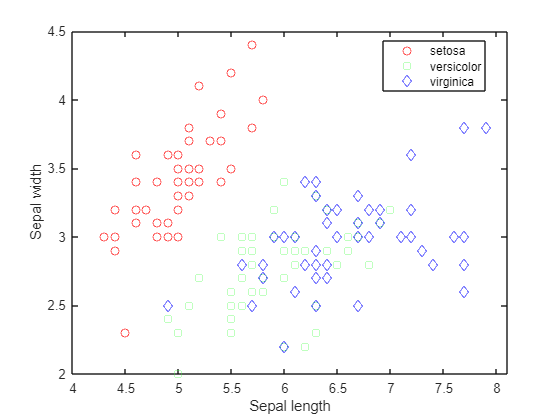

load fisheriris
gscatter(meas(:,1), meas(:,2), species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width');

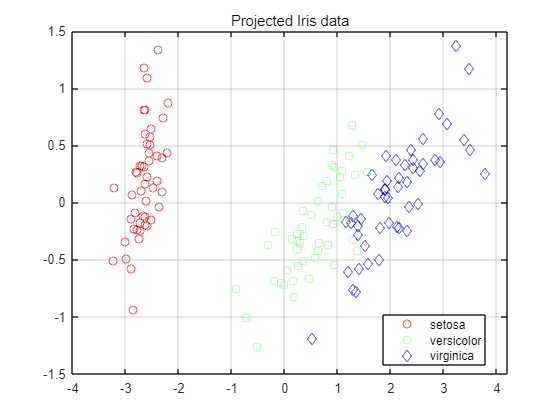

load('fisheriris');
m= mean(meas);
meas = meas - repmat(m, size(meas,1), 1);
covar = cov(meas);
[v, d] = eigs(covar);
top_two_eigenvectors = v(:,1:2);
score = meas*v(:,1:2);
figure(2)
gscatter(score(:,1), score(:,2), species, 'rgb','osd')
title('Projected Iris data'), grid on

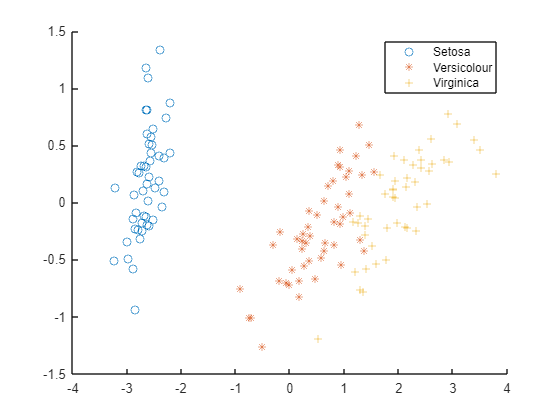


figure(3)
hold on;
plot(score (1:50, 1), score(1:50, 2), 'o');
plot(score (51:100, 1), score(51:100, 2), '*');
plot(score (101:150, 1), score(101:150, 2), '+');
hold off;
legend('Setosa', 'Versicolour','Virginica');

load('fisheriris');
m= mean(meas);
meas = meas - repmat(m, size(meas,1), 1);
covar = cov(meas);
[v, d] = eigs(covar);
d;

d =     4.2282         0         0         0
         0    0.2427         0         0
         0         0    0.0782         0
         0         0         0    0.0238


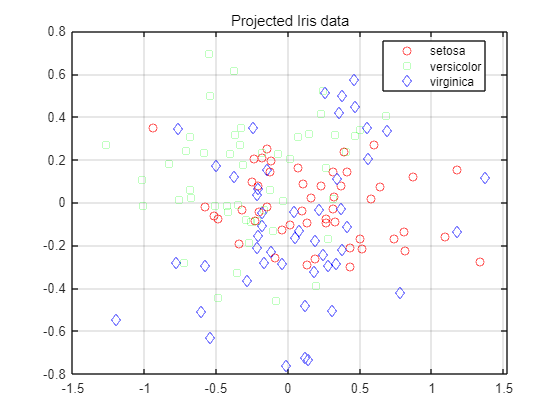

score = meas*v(:,2:3);
figure(2)
gscatter(score(:,1), score(:,2), species, 'rgb','osd')
title('Projected Iris data'), grid on

load fisheriris
a = zeros(size(species));
for i=1:max(size(a))
a(i) = isequal(species{i},'virginica');
end
label_vector = a;
instance_matrix = meas;
class1 = meas(a==1,:)

class1 =     6.3000    3.3000    6.0000    2.5000
    5.8000    2.7000    5.1000    1.9000
    7.1000    3.0000    5.9000    2.1000
    6.3000    2.9000    5.6000    1.8000
    6.5000    3.0000    5.8000    2.2000
    7.6000    3.0000    6.6000    2.1000
    4.9000    2.5000    4.5000    1.7000
    7.3000    2.9000    6.3000    1.8000
    6.7000    2.5000    5.8000    1.8000
    7.2000    3.6000    6.1000    2.5000


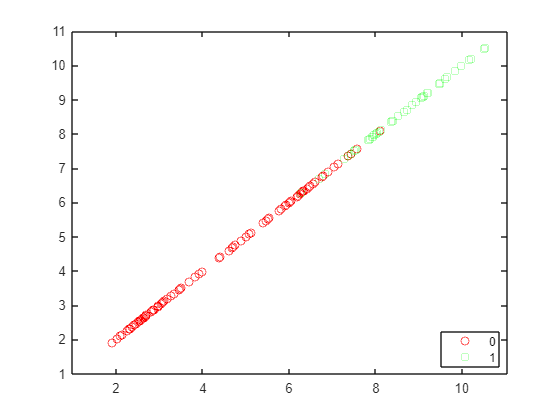

class0 = meas(a==0,:);
% class means
m1 = mean(class1);
m0= mean(class0);
% class covariance matrix
s1 = cov(class1);
s0 = cov(class0);
% within class scatter matrix
sw = s0 + s1;
% computing the LDA projection vector
v = inv(sw)*(m1-m0)';
% computing the projection score:
score = meas*v;
gscatter(score(:,1), score(:,1), a, 'rg','os') %% look at only one direction will be fine.